# **ECE 1473 OFDM Tutorial: **

# **Modulate Single Symbol of OFDM from Bits**

## **Author: Adam Nichols**

## Introduction:

Welcome to an introduction to OFDM digital modulation!

This set of MATLAB live scripts will be a tutorial on how to use communications concepts and modules to modulate OFDM.

## Background:

    What is OFDM? As per Couch in Digital and Analog Communications Systems: "Orthogonal Frequency Division Multiplexing (OFDM) is a technique for transmitting data in parallel by using a large number of modulated carriers with sufficient frequency spacing so that the carriers are orthogonal" [1]. The block diagram illustrating the modules of an OFDM modulator can be seen below in figure 1. 

    This means that OFDM sends many bits in parallel at the same time. For example, an OFDM signal could look like 1000 parallel bitstreams all packed together into one giant signal. These bits will be the Fourier Series Coefficients used in the IFFT algorithm to generate a digitally sampled analog signal. This analog symbol represents the baseband message that will be later sent over the air (OTA).

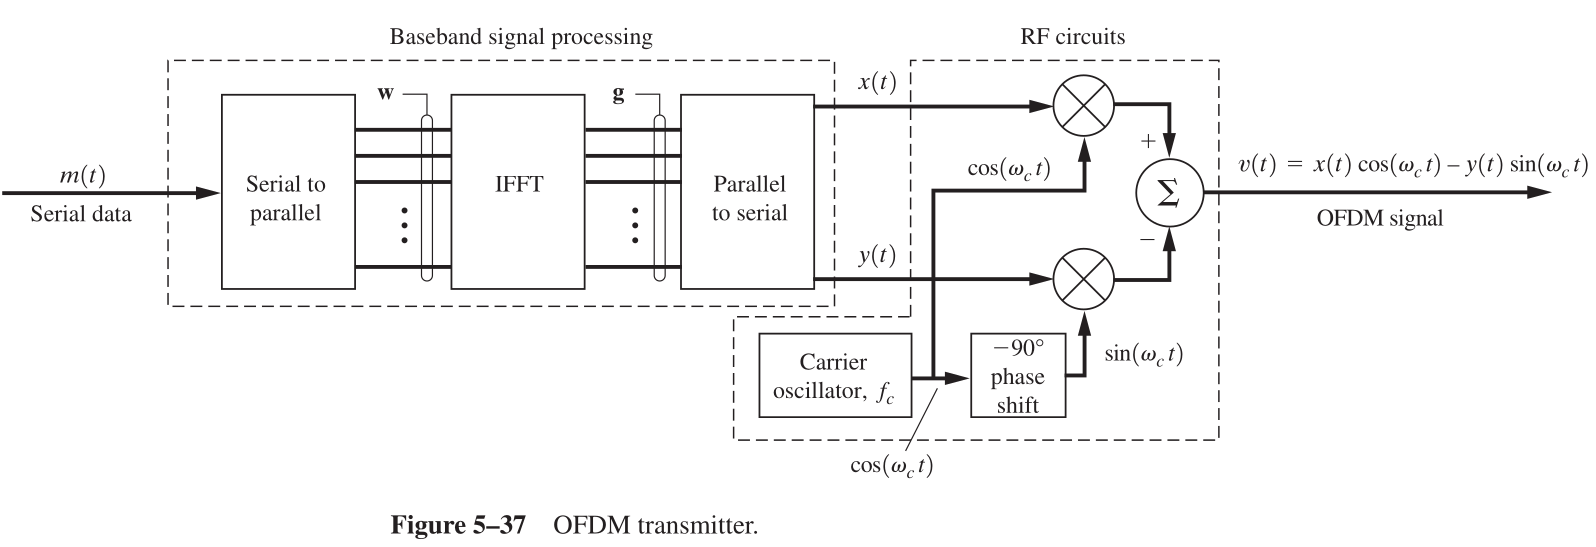

FIgure 1: Block diagram of OFDM transmitter from Couch [1]

    The parallelization used in OFDM has certain advantages in wireless communications, such as reducing the impact of multipath interference and narrowband jamming [1]. Further, any notch or narrowband interference may knock out only several bits of the entire 1000 bit symbol, but a single carrier modulation scheme would be completely disrupted. 

    OFDM is used in the physical layer of modern, high throughput and reliable communications systems and IOT devices [2]. Further, IEEE 802.11ax (a.k.a WiFi 6) uses an variant of OFDM called OFDMA (Orthogonal Frequency Division Multiple Access) to enable multiple users to access the same frequency channel [3]. OFDM is a very relevant topic in the modern wireless scene. 

## OFDM Single Symbol Modulation:

    The following MATLAB script will provide a method to modulate a simple, single symbol of OFDM. First, some data must be generated to be modulated with OFDM. For the purpose of this section, a set of random bits will be used. 

### Random Data Generation:

    First, choose a number of bits to send in a single symbol of OFDM. A default value of 32 is chosen to help illustrate different properties of OFDM later in this script.

num_bits = 32;

    All of these bits will be sent in one symbol of OFDM, so the number of bits will dictate the number of carriers used in this symbol. This variable used to represent the number of carriers will be the same as the number of bits for the binary case (this means each carrier will be BPSK - Binary Phase Shift Keying). The purpose of introducing this new variable is to provide clarity when referring to the signal in frequency domain contexts. 

    For higher order signal constellations the number of carriers could be different (less) than the number of bits. In these more advanced cases, larger constellations, like QPSK, 8PSK, 16QAM, etc. could be used to represent multiple bits in the space of one carrier. This tutorial only explores the BPSK case.

num_carriers = num_bits;

    Next, the random data will be generated. The following segment generates the random data using the rand function. Rand generates a vector of values uniformly distributed between 0 and 1. A vector of bits is generated by rounding (to nearest) each of these values to 0 or 1. The vector n represents the bit number associated with each bit.

bits = round(rand(num_bits,1));
n = transpose(0:num_bits-1);

    The following generates the stem plot to shown to the right to visualize the bits that will be sent. Before modulation, bits will take the value of 0 or 1. Remeber, all these bits are sent in parallel. This means that displayed on the right is the first bit of each bit stream. Keep this in mind when exploring the rest of this script.

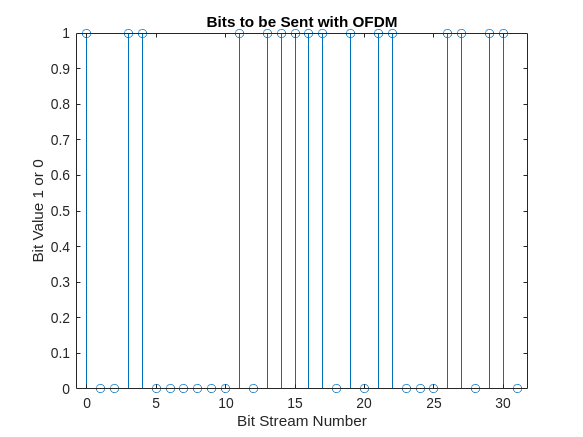

figure(1)
clf
stem(n, bits)
title("Bits to be Sent with OFDM")
xlabel("Bit Stream Number")
ylabel("Bit Value 1 or 0")

### Bitrate and OFDM Symbol Parameters:

    Next, several parameters of the OFDM modulation will be defined based on the bitrate and number of carriers chosen. The OFDM symbol rate and symbol time describe how often entire OFDM symbols are sent. The OFDM sample period and sample rate describe the timing information of the IFFT result. A time vector t is generated to plot against the time domain message.

    Use the drop down menu to select a bitrate.

bitrate = 1e4;
OFDM_symbolrate = bitrate / num_carriers;
OFDM_symboltime = 1/OFDM_symbolrate;
OFDM_sampleperiod = OFDM_symboltime / num_carriers;
OFDM_samplerate = 1/OFDM_sampleperiod;
t = transpose((0:num_bits-1)*OFDM_sampleperiod);

### Fourier Coefficients and Orthogonal Frequency Divisions:

    Next, these bits will be converted into Fourier series coefficients. Polar NRZ (non-return to zero) antipodal signalling will be used. This is a line code characterized by "Binary 1's and 0's are represented by equal positive and negative levels" and the pulse holds its value for its entire duration [1]. The data bits will be converted into antipodal bits so that 1's will take a value of 1 and 0's will take a value of -1. 

fourier_coeffs = bits*2 - 1;

    This bits will all be sent in parallel, as if each was sent in a separate bitstream on its own carrier frequency. The spacing of these frequencies is important to maintain orthogonality between the individual bitstreams. This means each bit may be recovered without interference from any other bit. Hence, OFDM contains orthogonal frequency division in its name.

     For two signals to be orthogonal, they must satisfy the following equation:

#### 
$$\int_0^T\phi_n(t)\phi_m^*(t)dt = 0 \qquad \forall \quad n \neq m$$


Equation 1: Definition of orthogonality [4]

where T represents the symbol time of the whole OFDM symbol and $\phi_n(t)$ and $\phi_m^*(t)$ represent two signals of interest ($\phi_m(t)$ had its complex conjugate taken). This definition of orthogonality is achievable for binary signal carriers when the minimum spacing between adjacent carriers is chosen such that:

#### 
$$f_{n+1} - f_n = \frac{1}{T}$$


Equation 2: Minimum frequency spacing for orthogonal frequency divisions [4]

A visual representation of this spacing can be seen in figure 2 below. Each signal represents a square wave containing random data, which has a power spectral density related to the sinc function.

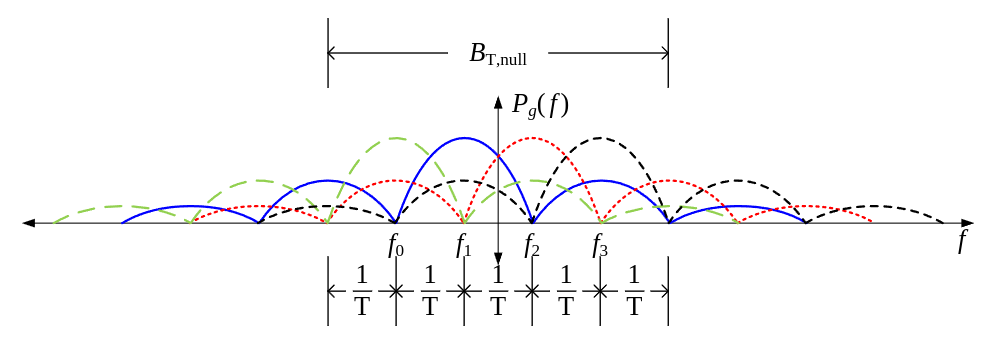

Figure 2: Frequency spacing of individual bits in OFDM composite baseband message [4]

    To create the orthogonal spacing, the following equation is used to generate the carrier frequencies for each parallel bitstream [1]:

#### 
$$f_n = \frac{1}{T}(n-\frac{N-1}{2})$$


where T represents the entire symbol time for one OFDM symbol and N represents the number of carriers. As per Couch, if the frequency offset of 

fourier_coeffs_freqs = 1/OFDM_symboltime*n;

    These coefficients are shown in a stem plot on the sidebar. These DFT Fourier coefficients represent the bits that will be sent using OFDM.

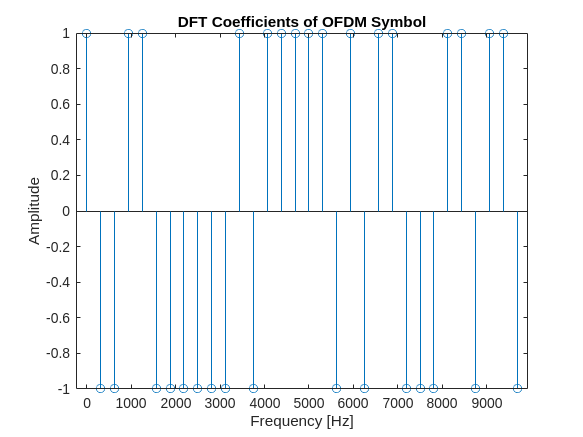

figure(2)
clf
stem(fourier_coeffs_freqs, fourier_coeffs)
title("DFT Coefficients of OFDM Symbol")
xlabel("Frequency [Hz]")
ylabel("Amplitude")

### IFFT Modulation:

    Next, the IFFT is performed on the Fourier coefficients to get the time domain signal. Since the data is random and without any particular symmetry, the signal will be complex and contain both real and imaginary components. The expression for the IFFT (or inverse DFT) is seen below (Couch equation 2-177) [1].

#### 
$$x[k] = \frac{1}{N}  \sum_{n=0}^{n=N-1}X[n]e^{j(2\pi/N)nk}$$


s_t = ifft(fourier_coeffs);

    The output of the IFFT is plotted against time. This plot represents the time domain signals (real and imaginary components) in the baseband message that represent the bits in an analog channel. The waveform is quite jagged because this is the minimum samples required to represent the data. Later, upsampling will be used to see a better representation of what the signal will look like in an analog channel.

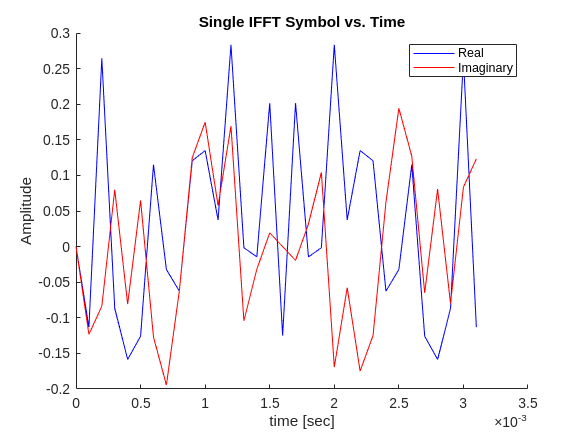

figure(3)
clf
hold on
plot(t, real(s_t), 'b-')
plot(t, imag(s_t), 'r-')
hold off
title("Single IFFT Symbol vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

    To verify the output of the IFFT accurately represents the bits, the magnitude spectrum is generated and plotted. The spectrum has a flat response, which is exactly what is expected. All the Fourier coefficients take a value of 1 or -1, so when the absolute value is taken just all 1's remain. Then, the amplitude of the spectrum is reduced by a factor of the bitrate. This yields the expected flat response.

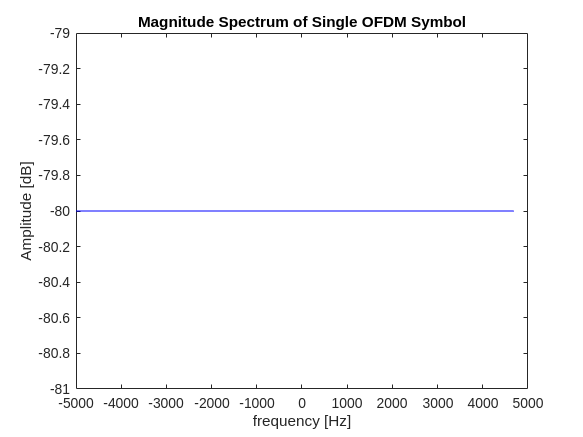

[f, spec] = GetSpectrum(s_t, OFDM_samplerate);
mag_spec = 20*log10(abs(spec));
figure(4)
clf
plot(f, mag_spec, 'b-')
title("Magnitude Spectrum of Single OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")

### Upsampling the Baseband Message:

    Next, the baseband signal is upsampled to understand out-of-band performance of OFDM modulation. This also has the benefit of better visualization of the OFDM signal on an analog channel. The resample function is used here because it uses sinc interpolation to generate intermediate values between samples without distorting spectral properties. To make the resulting signal periodic, the resample function will be used on three copies of the original message concatenated. The resulting middle copy will be sliced out and used. 

    Use the dropdown menu to choose an upsampling rate. A default upsampling rate of 8 samples/sample is used, but higher or lower values may be chosen. The parameters of sampling will be updated based on the chosen value. 

upsamp = 8;
OFDM_samplerate_upsamp = OFDM_samplerate*upsamp;
OFDM_sampleperiod_upsamp = OFDM_sampleperiod/upsamp;
s_t_triple = [s_t; s_t; s_t];
s_t_triple_upsamp = resample(s_t_triple,upsamp,1);
s_t_upsamp = s_t_triple_upsamp(upsamp*num_bits+1:2*upsamp*num_bits);
t_upsamp = transpose((0:upsamp*num_bits-1)*OFDM_sampleperiod_upsamp);

    The upsampled message is plotted against time. Through upsampling, this plot shows a more accurate representation of the baseband signal on a bandlimited analog channel. 

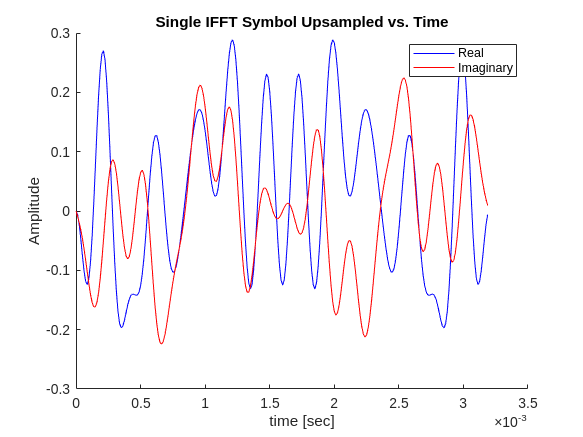

figure(5)
clf
hold on
plot(t_upsamp, real(s_t_upsamp), 'b-')
plot(t_upsamp, imag(s_t_upsamp), 'r-')
hold off
title("Single IFFT Symbol Upsampled vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

    Next, the spectrum of the upsampled baseband message is computed. Before, only frequencies up to half of the bitrate could be viewed and the spectrum showed a flat response. With an increased sampling rate, higher frequencies may be viewed in the spectrum. This will show how the OFDM signal performs outside of its ideal bandwidth. Note that inside the bandwidth, the signal is very flat with small ripple. Then, the signal drops off very sharply and reduces by -40dB immediately. Some rolloff after this point can be attributed to round-off error and windowing effects.

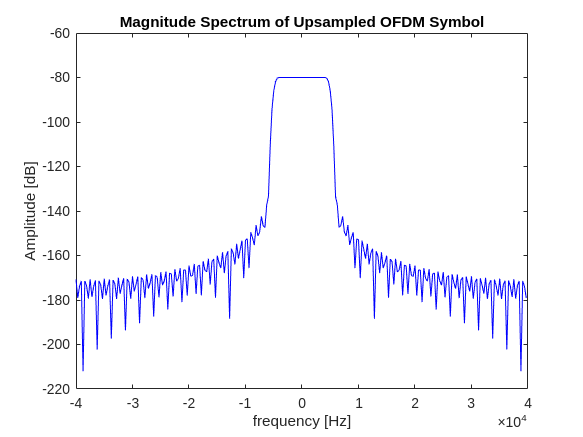

[f_upsamp, spec_upsamp] = GetSpectrum(s_t_upsamp, OFDM_samplerate_upsamp);
mag_spec_upsamp = 20*log10(abs(spec_upsamp));
figure(6)
clf
plot(f_upsamp, mag_spec_upsamp, 'b-')
title("Magnitude Spectrum of Upsampled OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")

### Adding More Symbols and Guard Intervals:

    Now, to send more data over the channel, more OFDM symbols must be sent over the air. To send more symbols, a silent guard interval will be introduced to begin simulating the windowing effects of OFDM. First, the baseband signal is zero padded by adding  many extra zero values to the outer bounds of the signal. The time values are adjusted to appropriately represent the new zero samples with the reference of $t = 0$ at the first sample of the OFDM symbol.

t_padded = transpose((-num_bits*upsamp:2*num_bits*upsamp-1)*OFDM_sampleperiod_upsamp);
s_t_padded = zeros(3*num_bits*upsamp, 1, 'like', 1j);
s_t_padded(num_bits*upsamp+1:2*num_bits*upsamp) = s_t_upsamp;


    The zero padded message is plotted on the left. Notice that the OFDM symbol may not start or end at exactly zero, which contributes to spurs. Additionally, there are discontinuities due to the derivative not being a continuous function. Both of these contribute to higher frequency distortion. Zoom in to the plot for "Single IFFT Symbol vs. Time" to view with greater detail.

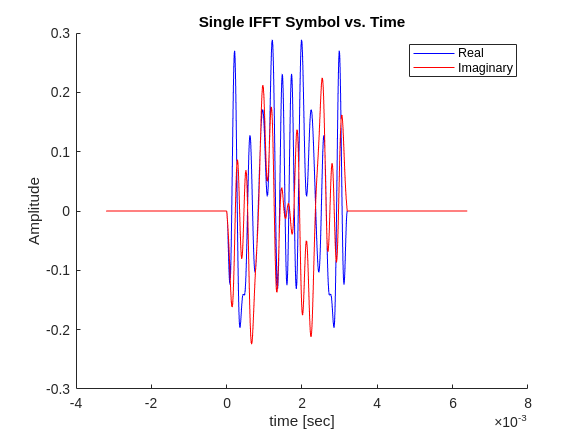

figure(7)
clf
hold on
plot(t_padded, real(s_t_padded), 'b-')
plot(t_padded, imag(s_t_padded), 'r-')
hold off
title("Single IFFT Symbol vs. Time")
xlabel("time [sec]")
ylabel("Amplitude")
legend("Real","Imaginary")

    Finally, the spectrum of the zero padded message is computed and plotted on the right. The distortion due to windowing is visible throughout the spectrum. In the bandwidth of the signal, significantly more ripple is visible due to the rectangular window and more frequency bins. Outside the signal bandwidth, there is also more ripple and the signal amplitude increases. This is not desireable when trying to conform to FCC specifications for a frequency band.

[f_padded, spec_padded] = GetSpectrum(s_t_padded, OFDM_samplerate_upsamp);
mag_spec_padded = 20*log10(abs(spec_padded));

    The spectra for the zero padded message and original message are plotted on the same axes. The high frequency windowing effects are visible here. The blue spectrum represents the original message and the red spectrum represents the zero padded signal. Zoom in to the plot on the right to see in greater detail (there is a great amount of overlap).

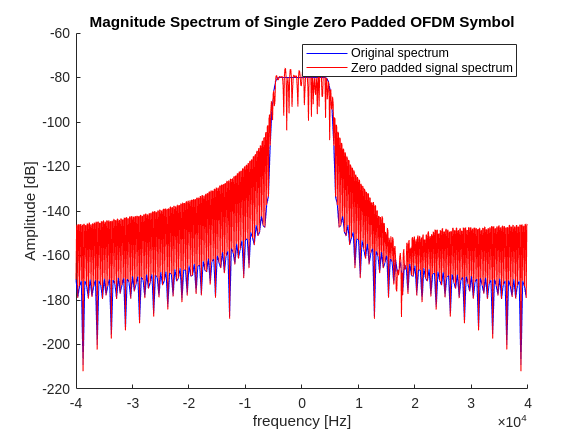

figure(8)
clf
hold on
plot(f_upsamp, mag_spec_upsamp, 'b-')
plot(f_padded, mag_spec_padded, 'r-')
title("Magnitude Spectrum of Single Zero Padded OFDM Symbol")
xlabel("frequency [Hz]")
ylabel("Amplitude [dB]")
legend("Original spectrum","Zero padded signal spectrum")

## Summary:

- OFDM transmits data by sending many bits in parallel bitstreams.

- OFDM uses data bits as Discrete Fourier Transform coefficients.

- OFDM is modulated with the IFFT function.

## Functions:

% GetSpectrum gets the spectrum of the input signal
% uses the fftshift function to make DC appear at center term
function [f,spectrum] = GetSpectrum(samples, sample_rate)

    % determine the spectrum of the baseband signal
    spectrum = 1/sample_rate*fftshift(fft(samples));
    
    % get bin numbers (centered at 0)
    f_bins = (0:length(samples)-1) - floor(length(samples)/2);

    % define the frequency range
    f = transpose(f_bins * sample_rate / length(f_bins));
end

## References:

[1] L. W. Couch, *Digital and Analog Communication Systems*. Upper Saddle River, N.J: Pearson, 2013. 

[2] “Wi-Fi: Overview of the 802.11 physical layer and transmitter measurements,” Tektronix, https://www.tek.com/en/documents/primer/wi-fi-overview-80211-physical-layer-and-transmitter-measurements (accessed Feb. 16, 2025). 

[3] R. Awati and L. Fitzgibbons, “What is OFDMA (orthogonal frequency-division multiple access)?: Definition from TechTarget,” Search Networking, https://www.techtarget.com/searchnetworking/definition/orthogonal-frequency-division-multiple-access-OFDMA (accessed Feb. 16, 2025). 

[4] Dr. S. Jacobs, “Unit 8 Lecture 2 - FDM and OFDM,” University of Pittsburgh.

‌